# Refining Feature Detection

In this reading, you will detect corner features on this image of a chessboard table using the Harris-Stephens algorithm, as shown below: 

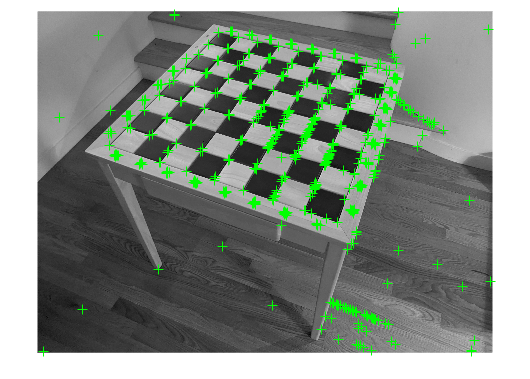

% Read in the image and convert to grayscale
chesstableRGB = imread("chesstable.jpg");
chesstable = im2gray(chesstableRGB);

% Detect corner features
corners = detectHarrisFeatures(chesstable);

% Display the image and features
imshow(chesstable)
hold on
plot(corners)
hold off

Recall from the previous discussion prompt that you aren't interested in all the features in the image, only the ones on the face of the table. This reading will guide you through a few techniques you can use to filter and refine the detected features. 

## Selecting Strongest Features

Start by using the `selectStrongest` function to only visualize the 300 "strongest" features in the image, or the ones that have the highest metric values.

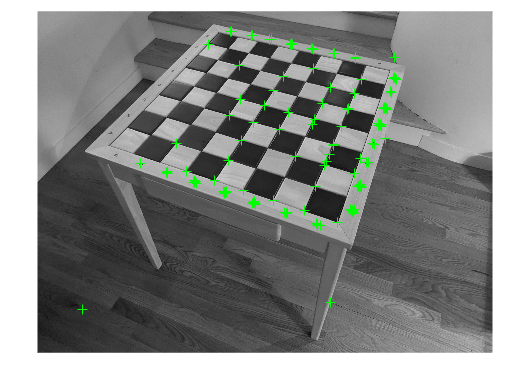

imshow(chesstable)
hold on
% Display strongest corner features
plot(selectStrongest(corners,148))
hold off

As you change the number of strongest features, notice that the features on the surface of the chess table are not always the strongest ones, so this technique isn't the best option for us here. Let's try another approach using one of the options of `detectHarrisFeatures`.

## Changing Filter Size

You may notice that a lot of the corners detected are unexpected due to the high resolution of the image. You can change the level of detail used to detect features by using the `"FilterSize"` option of `detectHarrisFeatures`. This value represents the Gaussian filter dimension used to smooth the gradient of the input image. In other words, increasing the value from its default of 5 to another odd integer will detect features in the more smoothed, or blurred, version of the input image.

You can visualize the results for different values of `"FilterSize"` below.

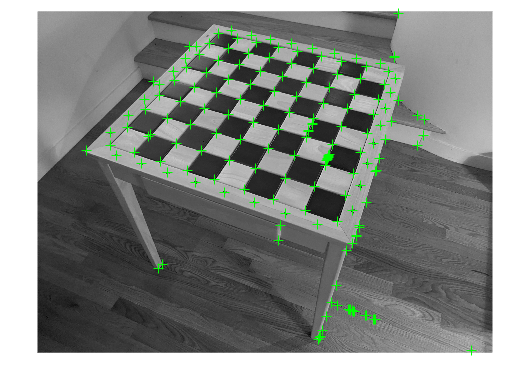

% Detect corner features using different values for FilterSize
chessCorners = detectHarrisFeatures(chesstable,"FilterSize",45);

% Display the result
imshow(chesstable)
hold on
plot(chessCorners)
hold off

As `"FilterSize"` gets larger, the smoothed image looks increasingly different from the original image. The detected features may not look like the ones we expect to see, but the number of detected features does tend to decrease. However, we're still unable to focus only on the features on the chessboard surface. There's one more important approach to try-- defining a specific region of interest.

## Region of Interest

Another possibility is to use the region of interest, or `"ROI"`, option to ensure your algorithm only focuses on a specific area of the image. Use the below code to create your region of interest, and then detect corner features only in that region

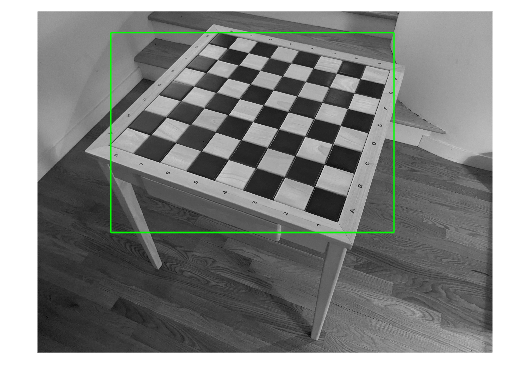

% Choose your region of interest
% The first 2 values represent the location of the upper-left corner.
% The last 2 values represent its width and height.
chesstableROI = [650,190,2510,1770];

% Display rectangle representing that region
imshow(chesstable)
rectangle("Position",chesstableROI,"EdgeColor","g")

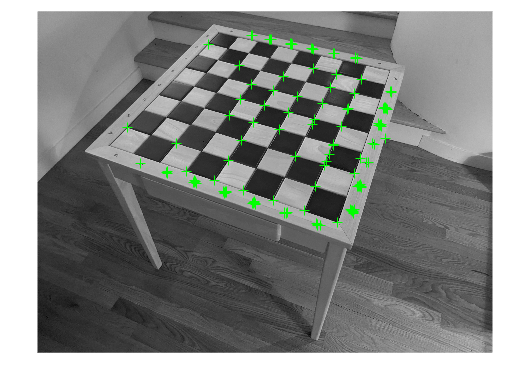

% Detect features in that region
cornersROI = detectHarrisFeatures(chesstable,"ROI",chesstableROI);

% Visualize the strongest features
imshow(chesstable)
hold on
plot(selectStrongest(cornersROI,150))
hold off

This looks much better! Almost every detected feature is now on the table surface. 

Other detection functions also have different options like `"ROI"`, so when you're not satisfied with the results from your detection step, be sure to check out the documentation to see which options you can use to fine tune your results.

## Further Exploration

In this reading, we focused on refining the results from the Harris detection algorithm, but there are many other detection algorithms you could explore instead! Refer to the documentation to learn more:

- [FAST](https://www.mathworks.com/help/vision/ref/detectfastfeatures.html)

- [Min Eigenvalue](https://www.mathworks.com/help/vision/ref/detectmineigenfeatures.html)

- [BRISK](https://www.mathworks.com/help/vision/ref/detectbriskfeatures.html)

- [ORB](https://www.mathworks.com/help/vision/ref/detectorbfeatures.html)

- [SIFT](https://www.mathworks.com/help/vision/ref/detectsiftfeatures.html)

- [KAZE](https://www.mathworks.com/help/vision/ref/detectkazefeatures.html)

*Copyright 2022 The MathWorks, Inc.*